load ("carsmall.mat")

x = Weight

x =         3504
        3693
        3436
        3433
        3449
        4341
        4354
        4312
        4425
        3850


y = Acceleration

y =    12.0000
   11.5000
   11.0000
   12.0000
   10.5000
   10.0000
    9.0000
    8.5000
   10.0000
    8.5000


z = MPG

z =     18
    15
    18
    16
    17
    15
    14
    14
    14
    15


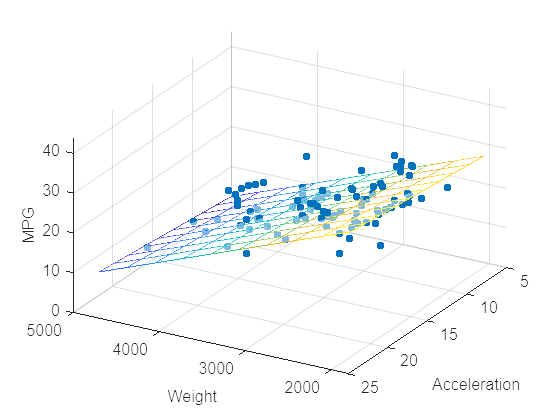


xv = linspace(min(x), max(x), 10)';
yv = linspace(min(y), max(y), 10)';
[X,Y] = meshgrid(xv, yv);
Z=reshape([ones(size(X(:))), X(:), Y(:)] * ...
mdl.Coefficients.Estimate, numel(xv), []);
figure,
scatter3(x,y,z, 'filled')
hold on
mesh(X, Y, Z, 'FaceAlpha', 0.5)
hold off
view(-150, 35)
set(gca,'fontsize',12)
xlabel('Weight', 'fontsize', 12)
ylabel('Acceleration', 'fontsize', 12)
zlabel('MPG', 'fontsize', 12)


tbl =...
table(Weight,Acceleration,Model_Year,MPG,...
'VariableNames',{'Weight','Acceleration',...
'Model_Year','MPG'});
mdl = fitlm(tbl,'MPG~Weight+Acceleration');